% % 
TR = delaunayTriangulation(TR.Points)

TR =   delaunayTriangulation with properties:

              Points: [9789×2 double]
    ConnectivityList: [19256×3 double]
         Constraints: []


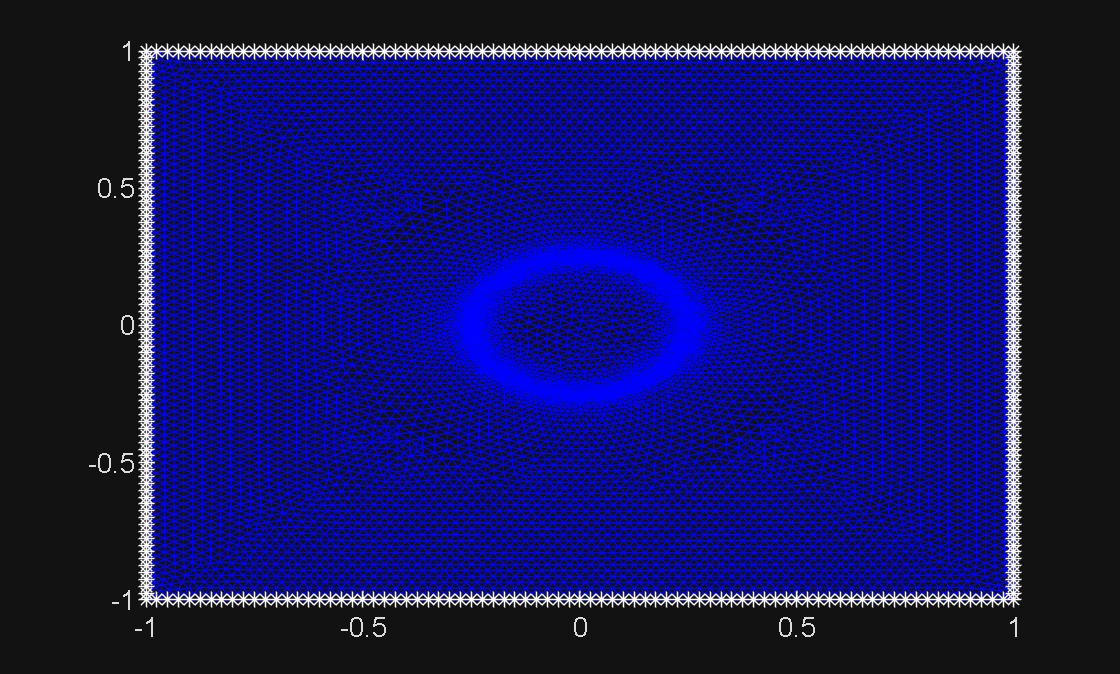

FB = freeBoundary(TR);
Rt = TR.Points;
I = 1:size(Rt,1);
I(FB) = [];
perm = [I FB(:,1)']';

xt = Rt(:,1);
yt = Rt(:,2);

x = Rt(I,1);
y = Rt(I,2);

% xt = xt(perm);
% yt = yt(perm);

triplot(TR)
hold on
plot(xt(FB),yt(FB),'*w')